# Reflection Matrix in Gaussian-Beam Basis

In this example, we compute the reflection matrix of an open system with the input and output bases being Gaussian beams focused to different spatial locations. The magnitude of the diagonal elements of this matrix corresponds to what is measured in confocal microscopy. We first build the list of inputs B and list of outputs C, and then use mesti() to compute the reflection matrix.

## Build the system

In this example, we consider a test system of a dielectric cylinderical scatterer located at $\left(x_0 ,y_0 \right)$ in air.

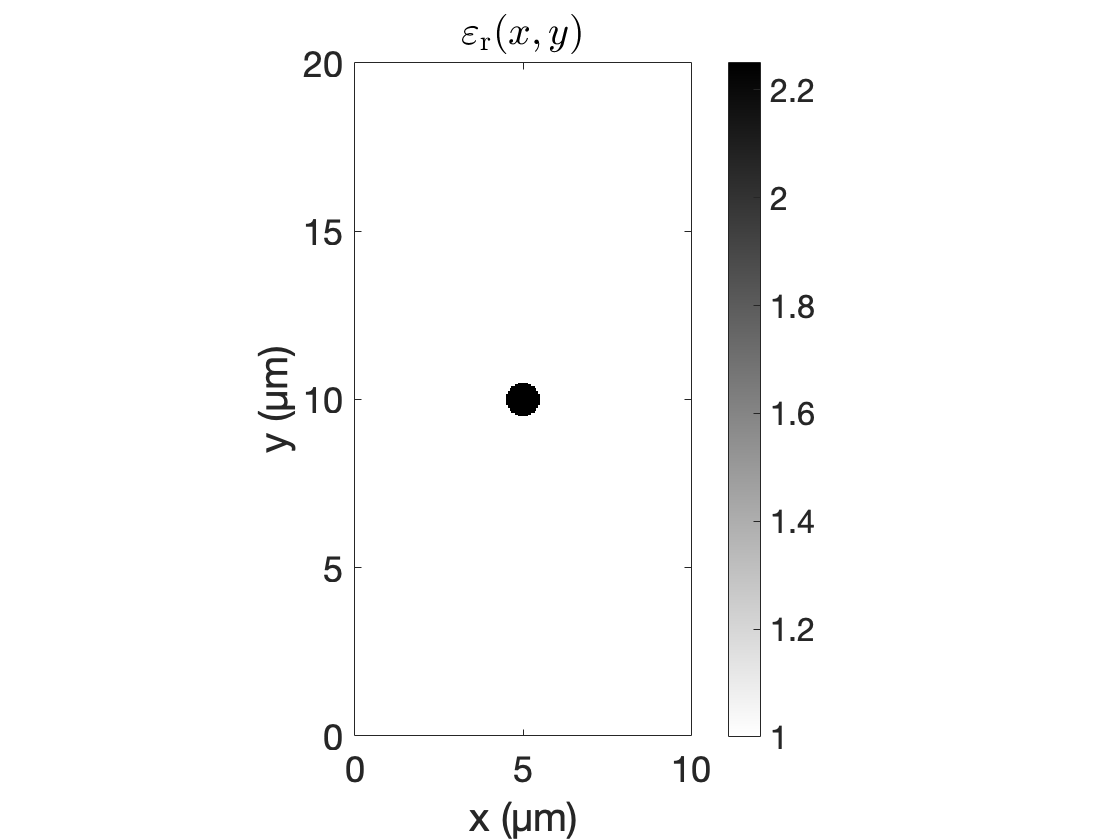

clear

% System parameters
syst.length_unit = 'µm';
syst.wavelength = 1.0; % wavelength (µm)
syst.dx = syst.wavelength/20; % discretization grid size (µm)
nPML = 20;    % number of PML pixels  
W = 20;       % width of simulation domain (including PML) (µm)
L = 10;       % length of simulation domain (including PML) (µm)
r_0 = 0.5;    % cylinder radius (µm)
n_bg   = 1.0; % refractive index of the background
n_scat = 1.5; % refractive index of the cylinder

% Build the relative permittivity profile
nx = round(L/syst.dx);
ny = round(W/syst.dx);
x = (0.5:nx)*syst.dx;
y = (0.5:ny)*syst.dx;
x_0 = L/2;  % location of the cylinder
y_0 = W/2;  % location of the cylinder
[X, Y] = meshgrid(x, y);
epsilon = n_bg^2*ones(ny, nx);
epsilon((X-x_0).^2+(Y-y_0).^2 < r_0^2) = n_scat^2;

% Plot the relative permittivity profile
figure
imagesc(x, y, epsilon)
set(gca,'YDir','normal')
colorbar
colormap(flipud(gray))
title('$\varepsilon_{\rm r}(x,y)$','Interpreter','latex')
xlabel('x (µm)')
ylabel('y (µm)')
axis image
set(gca, 'FontSize', 18)

## Build the input sources

We consider inputs being Gaussian beams focused at $\left(x_{f\;} ,y_f \right)\;$. In this example, we fix the focal depth at $x_{f\;} =x_0$ (i.e., the depth of the scatterer), and scan the transverse coordinate $y_f$ of the focus.

   Perfect Gaussian beams can be generated with the total-field/scattered-field (TF/SF) method. But since the cross section of the beam decays exponentially in $y$, we can generate Gaussian beams to a high accuracy simply by placing line sources at a cross section on the left, which is what we do here. We place the line sources at $x=x_{\textrm{source}}$, just in front of the PML.

   To determine the required line sources, we (1) take the the field profile of the desired incident Gaussian beam at the focal plane, $E_z^{\textrm{in}} \left(x_f ,y\right)=E_0 \;\exp \left\lbrack -\frac{{\left(y-y_f \right)}^2 }{{w_0 }^2 }\right\rbrack \;$, (2) project it onto the propagating channels (i.e., ignoring evanescent contributions) of free space, (3) back propagate it to the source plane to determine $E_z^{\textrm{in}} \left(x_{\textrm{source}} ,y\right)$ in the propagating-channel basis, and (4) determine the line source necessary to generate such $E_z^{\textrm{in}} \left(x_{\textrm{source}} ,y\right)$.

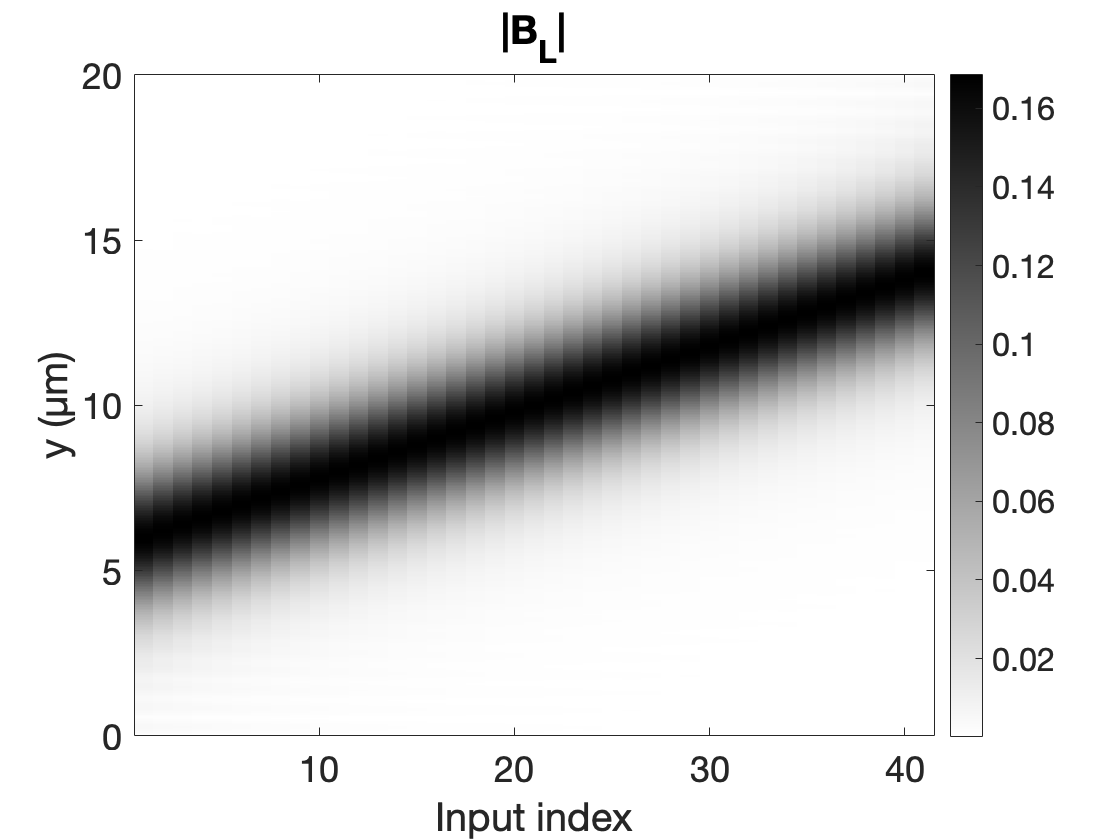

% Parameters of the input Gaussian beams
NA = 0.5;   % numerical aperture
x_f = x_0;  % location of the focus in x (fixed)
y_f_start = 0.3*W; % starting location of the focus in y 
y_f_end   = 0.7*W; % ending location of the focus in y
dy_f = syst.wavelength/(10*NA);  % spacing of focal spots in y

% Parameters of the line sources
n_source = nPML + 1; % index of the source plane
x_source = x(n_source); % location of the source plane

w_0 = syst.wavelength/(n_bg*pi*NA); % beam radius at x = x_f
y_f = y_f_start:dy_f:y_f_end; % list of focal positions in y
M_in = length(y_f); % number of inputs

% Step 1: Generate the list of E^in(x=x_f, y).
% Here, y.' is an ny-by-1 column vector, and y_f is a 1-by-M_in row vector.
% So, y.' - y_f is an ny-by-M_in matrix by implicit expansion.
% Then, E_f is an ny-by-M_in matrix whose m-th column is the cross section
% of the m-th Gaussian beam at x = x_f.
E_f = exp(-(y.' - y_f).^2/(w_0^2)); % size(E_f) = [ny, M_in]

% Get properties of propagating channels in the free space.
% We use PEC as the boundary condition for such channels since the default
% boundary condition in mesti() is PEC, but the choice has little effect
% since E^in should be exponentially small at the boundary of the simulation
% domain.
channels = mesti_build_channels(ny,'PEC',(2*pi/syst.wavelength)*syst.dx,n_bg^2); 

% Transverse profiles of the propagating channels. Each column of phi is
% one transverse profile. Different columns are orthonormal.
phi = channels.fun_phi(channels.L.kydx_prop); % size(phi) = [ny, N_prop]

% Step 2: Project E^in(x_f, y) onto the propagating channels.
E_f_prop = phi'*E_f; % size(E_f_prop) = [N_prop, M_in]

% Step 3: Back propagate from x = x_f to x = x_source.
% This step assumes a PEC boundary in y, so it is not exact with PML in y,
% but it is sufficiently accurate since E^in decays exponentially in y.
% Note we use implicit expansion here.
kx = reshape(channels.L.kxdx_prop/syst.dx, [], 1); % list of wave numbers
E_s_prop = exp(1i*kx*(x_source-x_f)).*E_f_prop; % size(E_s_prop) = [N_prop, M_in]

% Step 4: Determine the line sources.
% In a closed geometry with no PML in y, a line source of
% -2i*mu(a)*phi(:,a) generates outgoing waves with transverse profile
% phi(:,a). With PML in y, this is not strictly true but is sufficiently
% accurate since E^in(x=x_source,y) decays exponentially in y.
% Note we use implicit expansion here.
mu = reshape(channels.L.sqrt_mu, [], 1).^2; % mu = sin(kx*dx)
B_L = phi*(mu.*E_s_prop); % size(B_L) = [ny, M_in]

% We take the -2i prefactor out, to be multiplied at the end. The reason
% will be clear when we handle C below.
opts.prefactor = -2i;

% In mesti(), B.pos specifies the position of a block source: [m1, n1, h, w],
% where (m1, n1) is the index of the smaller-(y,x) corner, and (h, w) is the 
% height and width of the block. Here, we put line sources (w=1) at n1 =
% n_source that spans the whole width of the simulation domain (m1=1,
% h=ny).
B.pos = [1, n_source, ny, 1]; 

% B.data specifies the source profiles. It is a 2D array here where
% B.data(:, a) stores the a-th input. We have M_in line sources with length ny 
% so size(B.data) = [ny, M_in].
B.data = B_L;

% We check that the input sources are sufficiently localized with little 
% penetration into the PML; otherwise the Gaussian beams will not be accurately 
% generated.
figure
imagesc([1, M_in], y, abs(B_L))
set(gca,'YDir','normal')
colorbar
colormap(flipud(gray))
title('|B_L|')
xlabel('Input index')
ylabel('y (µm)')
set(gca, 'FontSize', 18)

## Build the output projections

We consider output projections onto the same set of Gaussian beams focused at $\left(x_{f\;} ,y_f \right)\;$, with the projection done at the same plane as the source plane ($x=x_{\textrm{source}}$).

   When the system has a closed boundary in $y$, as is the case in mesti2s(), the set of transverse modes form a complete and orthonormal basis, so it is clear what the output projection should be. But the Gaussian beams here are not orthogonal to each other, are not normalized, and do not form a complete basis. So, it is not obvious how our output projection should be defined.

   What we do here is to convert everything onto the complete and orthonormal basis of transverse modes, and do the projection in such basis while accounting for the flux. Specifically, we (1) project the total field at the source plane, $E_z^{\textrm{tot}} \left(x_{\textrm{source}} ,y\right)=E_z^{\textrm{in}} \left(x_{\textrm{source}} ,y\right)+E_z^{\textrm{sca}} \left(x_{\textrm{source}} ,y\right)$ , onto the propagating channels (i.e., ignoring evanescent contributions) of free space; the incident contribution will be subtracted later (2) back propagate such reflection to the focal plane at $x=x_f$ since the$E_z^{\textrm{sca}} \left(x_{\textrm{source}} ,y\right)$ component supposedly comes from reflection, (3) take the previously computed Gaussian beams at the focal plane projected onto propagating channels of free space, and (4) take the inner product between the two while accounting for the longitudinal flux of the different propagating channels.

     Above, the incident field $E_z^{\textrm{in}} \left(x,y\right)$ was not subtracted. Contribution from the incident field will be subtracted using matrix D in the next step.

% We perform the output projection on the same plane as the line source.
C.pos = B.pos;

% Step 1: Project E(x_source, y) onto the propagating channels.
% The projection will be C_L*E(:,n_source).
C_L = phi'; % size(C_L) = [N_prop, ny]

% Step 2: Back propagate from x = x_source to x = x_f.
C_L = exp(-1i*kx*(x_f-x_source)).*C_L; % size(C_L) = [N_prop, ny]

% Step 3: Project Gaussian beams at the focal plane onto the propagating
% channels. No need to repeat since this was already done earlier.
% E_f_prop = phi'*E_f; % size(E_f_prop) = [N_prop, M_in]

% Step 4: Take the inner product between the two.
% The longitudinal flux of a propagating channels is proportional to mu, so
% we weight the inner product with mu to account for flux dependence.
% Note we use implicit expansion here.
C_L = (E_f_prop') * (mu.*C_L); % size(C_L) = [M_in, ny]

% Normally, the next step would be
% C.data = C_L.';
% However, we can see that C_L equals transpose(B_L).
fprintf('max(|C_L-transpose(B_L)|) = %g\n', max(abs(C_L - B_L.'), [], 'all'));

max(|C_L-transpose(B_L)|) = 1.38778e-16


% That means we will have C = transpose(B). So, we can save some computing
% time and memory usage by specifying C = transpose(B).
% This is expected by reciprocity -- when the set of inputs equals the set
% of outputs, we typically have C = transpose(B) or its permutation.
C = [];
opts.use_transpose_B = true;

## Compute reflection matrix in Gaussian-beam basis

The scattering matrix is given by S = C*inv(A)*B - D, with D = C*inv(A_0)*B - S_0 where A_0 is a reference system for which its scattering matrix S_0 is known. We consider A_0 to be a homogeneous space with no scatterers, for which the reflection matrix S_0 is zero.

syst.PML.npixels = nPML; % Put PML on all four sides

% For a homogeneous space, the length of the simulation domain doesn't
% matter. Thus we choose a minimal thickness of nx_temp = n_source + nPML,
% where n_source = nPML + 1 is the index of the source plane.
syst.epsilon = n_bg^2*ones(ny, n_source + nPML);
D = mesti(syst, B, C, [], opts);

System size: ny = 400, nx = 41
UPML on -x +x -y +y sides; xBC = PEC; yBC = PEC
Building B,C... elapsed time:   0.007 secs
Building A...   elapsed time:   0.026 secs
< Method: SCSA using MUMPS with AMD ordering >
Building K...   elapsed time:   0.004 secs
Analyzing...    elapsed time:   0.014 secs
Factorizing...  elapsed time:   0.100 secs
          Total elapsed time:   0.184 secs


% Compute the reflection matrix.
syst.epsilon = epsilon;
r = mesti(syst, B, C, D, opts);

System size: ny = 400, nx = 200
UPML on -x +x -y +y sides; xBC = PEC; yBC = PEC
Building B,C... elapsed time:   0.003 secs
Building A...   elapsed time:   0.037 secs
< Method: SCSA using MUMPS with AMD ordering >
Building K...   elapsed time:   0.019 secs
Analyzing...    elapsed time:   0.070 secs
Factorizing...  elapsed time:   0.602 secs
          Total elapsed time:   0.756 secs


## Compute the full field profile

For most applications, it is not necessary to compute the full field profile, since most experiments measure properties in the far field. Here, we compute the full field profile for the purpose of visualizing the system as the incident Gaussian beams are scanned across y.

opts.use_transpose_B = false; % C should not be used for field-profile computation
field_profiles = mesti(syst, B, [], [], opts);

System size: ny = 400, nx = 200
UPML on -x +x -y +y sides; xBC = PEC; yBC = PEC
Building B,C... elapsed time:   0.002 secs
Building A...   elapsed time:   0.046 secs
< Method: factorize_and_solve using MUMPS with AMD ordering >
Analyzing...    elapsed time:   0.072 secs
Factorizing...  elapsed time:   0.371 secs
Solving...      elapsed time:   0.558 secs
          Total elapsed time:   1.089 secs


## Animate the field profiles

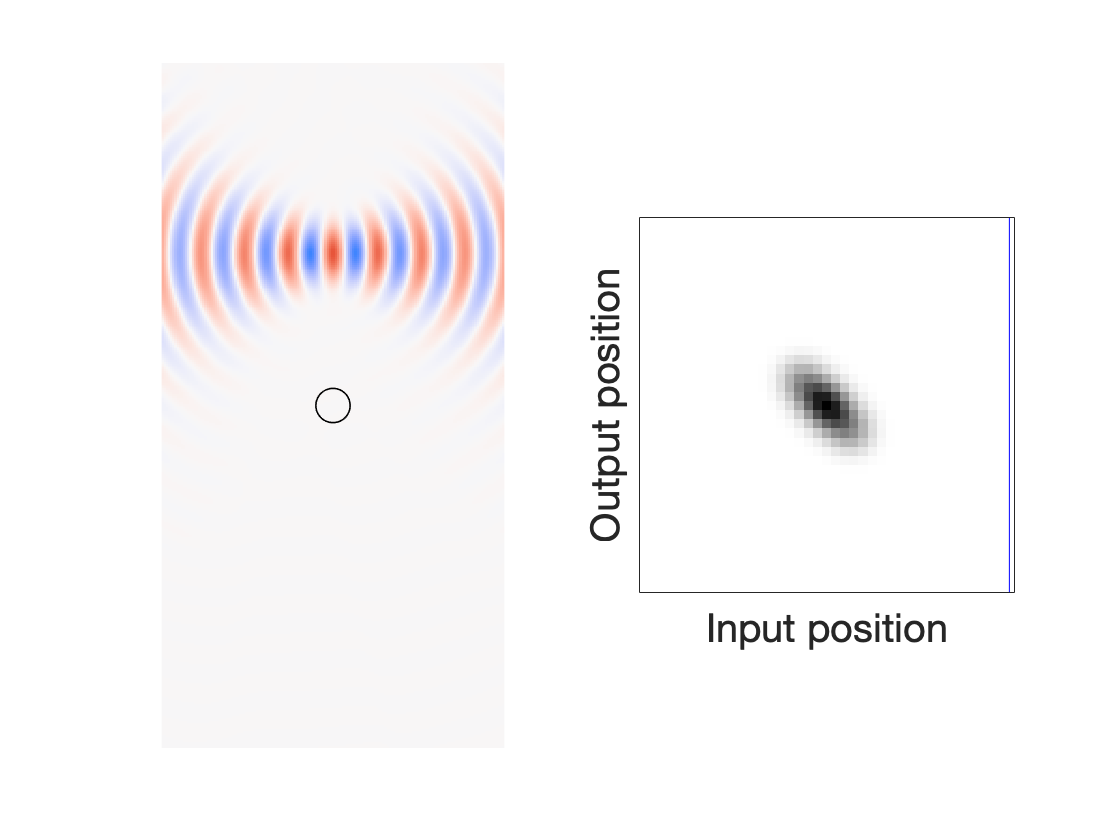

theta = linspace(0, 2*pi, 100);
circ_x = cos(theta);
circ_y = sin(theta);

cmap_bluered = colorcet('D09'); % use a blue-white-red colormap from colorcet

% Loop through Gaussian beams focused at different locations.
figure
for ii = 1:M_in
    % Plot the total field profile; exclude PML
    ax1 = subplot(1,2,1);
    imagesc(x, y, ...
        real(field_profiles((nPML+1):(ny-nPML), (nPML+1):(nx-nPML), ii)));
    set(gca,'YDir','normal')
    caxis([-1,1]) % center the colorbar axis so zero = white
    colormap(ax1, cmap_bluered);
    hold on
    plot(x_0+r_0*circ_x, y_0+r_0*circ_y, 'k-', 'linewidth', 0.8);
    axis image off
    
    % Plot the reflection matrix
    ax2 = subplot(1,2,2);
    imagesc(y_f, y_f, abs(r).^2)
    set(gca,'YDir','normal')
    colormap(ax2, flipud(gray))
    xlabel('Input position')
    ylabel('Output position')
    hold on
    % Show the current focal position
    plot(y_f(ii)*[1,1], get(gca,'YLim'), 'b-')
    axis image
    xticks([])
    yticks([])
    set(gca, 'FontSize', 18)
    drawnow
end